# Test cancer cell line encylopedia metabolic models

## Summary

This module determines whether the cancer cell line models from the CCLE data repository can output a feasible metabolic flux distribution.

## Load the eGEM

We'll optimize the biomass and ATP objective function for the eGEM models.

load 05042020eGEM.mat; model = eGEM;

% Turn off reactions that negatively affect model performance.
posToTurnOff                   = find(ismember(model.rxns, {'ALR', 'MGSA', 'MGSA2'}));
model.ub(posToTurnOff)         = 0; model.lb(posToTurnOff) = 0;
model.lb(ismember(model.rxns, ...
         'biomass_objective')) = 0; % Change the lower bound of the biomass objective function to 0. 

    
% Reset the primary objective function
model.c                        = zeros(size(model.c));
model.c(ismember(model.rxns, ...
    'biomass_objective'))      = 1;

## Set up a gurobi model

Gurobi needs several additional fields that are not part of the COBRA format. This block adds that here. 

% Set up Gurobi model
model.A   = model.S;
model.obj = model.c;
model.rhs = model.b;

if (exist('model.csense','var')) && (~isempty(model.csense))
    model.sense = model.csense;
    model.sense(ismember(model.sense,'E')) = '=';
    model.sense(ismember(model.sense,'L')) = '<';
    model.sense(ismember(model.sense,'G')) = '>';
else
    model.sense = repmat('=', [size(model.S, 1), 1]);
end
model.vtype      = repmat('C', size(model.S, 2), 1);
model.modelsense = 'max';

params.outputflag          = 0;
params.Threads             = 4;
params.Seed                = 314;
params.NumericFocus        = 3;

## Filter CCLE data based on intersection between microarray data and global chromatin profiles

load ccle_geneExpression_vars.mat
load CCLE_Proteomics.mat

% Get intersection indicies
[~, ia, ib] = intersect(string(celllinenames_ccle1), string(cell_names));

% Extract intersection data
microarray_cellnames = celllinenames_ccle1(ia);
microarray_data      = ccle_expression_metz(:, ia);
microarray_genenames = ccleids_met;

gcp_cellnames = cell_names(ib);
gcp_medium    = medium(ib);
gcp_data      = proteomics(ib, :);
gcp_culture   = cultures(ib, :);
gcp_tissue    = tissues(ib, :);

## Compute growth rates for the CCLE wild type models

hyperparams.eps  = [];
hyperparams.kap  = [];
hyperparams.rho  = [];
hyperparams.mode = true;
hyperparams.eps2 = [];
hyperparams.pfba = true;

mediumMap = 'FINAL_MEDIUM_MAP.xlsx';
for k = 1:length(ia)
    constrainedModel = model;
    mediumModel   = addMediumConstraints(constrainedModel, ...
                                         string(gcp_medium(k)),...
                                         mediumMap);     % Add on medium constraints
    diffExpGenes  = findDiffExpGenes(mediumModel, string(gcp_cellnames(k)));          % Find differentially expressed genes for this cancer cell line
    ON_fieldname  = string(strcat('ON_', string(gcp_cellnames(k))));                  % Make fieldnames for structure
    OFF_fieldname = string(strcat('OFF_', string(gcp_cellnames(k))));
    
    [~, soln] = CFR(mediumModel, hyperparams, ...
                    diffExpGenes.(ON_fieldname), ...
                    diffExpGenes.(OFF_fieldname));
    grate(k, 1) = soln.x(3743);
end

## Distribution of the CCLE model growth rates

To see how many cancer cell lines that are simulated actually give a biologically relevant flux distribution, I plotted the distribution of the growth rates on a histogram and boxplot

### All growth rates from the CCLE

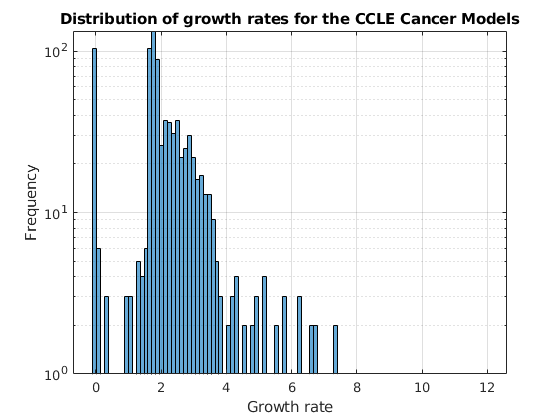

histogram(grate, 100);
set(gca, 'YScale', 'log');
xlabel('Growth rate'); ylabel('Frequency'); grid on
title('Distribution of growth rates for the CCLE Cancer Models')

### Partition the CCLE cell lines to subgroups

### Medium conditions

% Partition growth rates by medium
boxplot(categorical(gcp_medium), grate)

### Tissue lineage

% Partition growth rates by tissue
boxplot(categorical(gcp_tissue), grate)

### Cellular morphology

% Partition growth rates by morphology
boxplot(categorical(gcp_culture), grate)